clear all

data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;
eye(2)

ans =      1     0
     0     1


G1 = FWT(1:2,1:2)

G1 =
 
  A = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s        -0.422       -0.2204             0       -0.2204             0
   z1dot (m/s)        0.02328      -0.01085         -0.04     -0.009574             0
   z1 (m)                   0             1             0             0             0
   z2dot (m/s)         0.1455      -0.05984             0       -0.1651        -10.82
   z2 (m)                   0             0             0             1             0
 
  B = 
                 Beta (deg)  tau_e (Nm)
   Omega (rad/s    -0.07988   -0.009564
   z1dot (m/s)    -0.006722           0
   z1 (m)                 0           0
   z2dot (m/s)     -0.04202           0
   z2 (m)                 0           0
 
  C = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s             1             0             0             0             0
   z (m)                    0           

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = G1.C*inv((s*eye(5)-G1.A))*G1.B

G =
 
  From input 1 to output...
                                                                                               
       -0.07988 s^14 - 0.09884 s^13 - 2.654 s^12 - 2.906 s^11 - 29.62 s^10 - 28.22 s^9         
                                                                                               
               - 114.1 s^8 - 91.37 s^7 - 33.67 s^6 - 11.32 s^5 - 2.878 s^4 - 0.4741 s^3        
                                                                                               
                                                          - 0.09734 s^2 - 0.006633 s - 0.001154
                                                                                               
   1:  ----------------------------------------------------------------------------------------
                                                                                               
       s^15 + 1.794 s^14 + 34 s^13 + 53.72 s^12 + 391.7 s^11 + 533.8 s^10 + 1611 s^9           
      

omega = [0, 0.6*pi];
    for i =1:length(omega)
        Gf=freqresp(G,omega(i));
        RGAw(:,:,i)=Gf.*inv(Gf).';
        RGAno(i)=sum(sum(abs(RGAw(:,:,i)-eye(2))));
        
    end
    RGA = frd(RGAw,omega)

RGA =

  From input 1 to:

    Frequency(rad/s)         output 1          output 2    
    ----------------         --------          --------    
         0.0000         -0.6554 + 0.0000i  1.6554 + 0.0000i
         1.8850         -0.0283 + 0.1398i  1.0283 - 0.1398i

  From input 2 to:

    Frequency(rad/s)        output 1           output 2    
    ----------------        --------           --------    
         0.0000         1.6554 + 0.0000i  -0.6554 + 0.0000i
         1.8850         1.0283 - 0.1398i  -0.0283 + 0.1398i
 
Continuous-time frequency response.



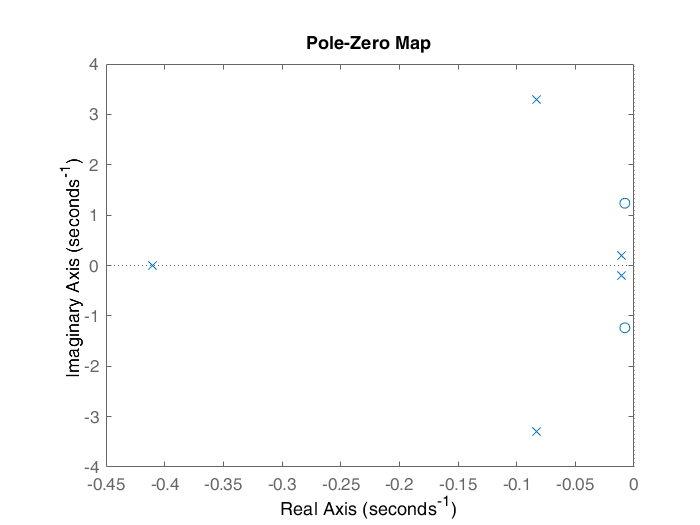

pzplot(FWT(1:2,1:2))

poles = pole(FWT(1:2,1:2))

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


zeros = zero(FWT(1:2,1:2))

zeros =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i



G=tf(FWT(1:2,1:2))

G =
 
  From input "Beta (deg)" to output...
                   -0.07988 s^4 - 0.003315 s^3 - 0.8677 s^2 + 0.006493 s - 0.03458
   Omega (rad/s):  ---------------------------------------------------------------
                    s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
                  -0.04874 s^3 - 0.03481 s^2 - 0.07497 s - 0.052
   z (m):  ------------------------------------------------------------
           s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
  From input "tau_e (Nm)" to output...
                   -0.009564 s^4 - 0.001683 s^3 - 0.1039 s^2 - 0.001187 s - 0.00414
   Omega (rad/s):  ----------------------------------------------------------------
                     s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
                      -0.001614 s^2 - 2.522e-05 s - 0.002465
   z (m):  ------------------------------------------------------------
           s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827


wB1=0.3*2*pi; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/1000; % desired disturbance attenuation inside bandwidth
M=3 ; % desired bound on hinfnorm(S)
Wp11=tf([1/M wB1],[1 wB1*A])

Wp11 =
 
  0.3333 s + 1.885
  ----------------
    s + 0.001885
 
Continuous-time transfer function.



Wp=[Wp11 0; 0 wB2] %

Wp =
 
  From input 1 to output...
       0.3333 s + 1.885
   1:  ----------------
         s + 0.001885
 
   2:  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
Continuous-time transfer function.



%Sensitivity weight
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []




P11=[Wp;eye(2)];
P12=[Wp*G;Wu];
P21=eye(2);
P22=G;

%P=[P11 P12; P21 P22]
P = augw(minreal(G),Wp,Wu,Wt)

P =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8
   x1   -0.001885          0          0     0.1598   0.001658     0.4338  -0.006493     0.1383
   x2           0    -0.0014  -0.001024          0          0          0          0          0
   x3           0  0.0009766          0          0          0          0          0          0
   x4           0          0          0    -0.5979     -2.744     -1.177     -0.271    -0.3654
   x5           0          0          0          4          0          0          0          0
   x6           0          0          0          0          1          0          0          0
   x7           0          0          0          0          0        0.5          0          0
   x8           0          0          0          0          0          0       0.25          0
   x9           0          0          0          0          0          0          0          0
   x10          0          0         

P=minreal(P)

5 states removed.

P =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     0.2599   -0.02928     0.0482     -1.296      0.492     0.2111    0.02852    0.05985
   x2     0.4368   -0.02871  9.475e-05     0.2511    -0.4436   0.005374   -0.03356   -0.02297
   x3     -0.017     0.2545   -0.01446    -0.1435     0.1579    -0.0246    0.05709  0.0007788
   x4     0.7173    -0.1849     0.2458     0.1783     -3.349     -1.204    -0.3704     -0.383
   x5     -1.187    -0.1157    -0.3366      2.576    -0.6386    -0.5083   -0.05646    -0.1604
   x6    -0.6268   -0.05347    -0.1519     0.6166    -0.3688    -0.3668   -0.04518    -0.1098
   x7    -0.2037   -0.03706   -0.08398     0.2701    -0.2517    -0.1733   -0.03015   -0.05972
   x8      0.209    0.03026    0.07609     0.2827   0.004765     0.1196    0.01227    0.03924
 
  B = 
                ?           ?  Beta (deg)  tau_e (Nm)
   x1     0.05558           0    -0.05566    0.009356
   x2

[K2,CL2,GAM2,INFO2] = hinfsyn(P,2,2)

K2 =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1    17.98    2.971   -16.95   0.5649    3.724   -10.29   -48.79    114.5
   x2   -19.24   -2.031    18.33   -2.068    -4.97    13.23    51.97   -120.5
   x3    6.529    1.374   -6.197   0.5372    1.346   -3.775   -17.78    41.87
   x4    40.82    6.458    -38.1    4.415    4.069   -25.08   -110.5    257.6
   x5   -166.4   -24.92    156.7   -15.37   -33.01      101    449.5    -1051
   x6   -72.09   -9.609    67.46   -7.378   -15.19    45.12    192.8   -449.5
   x7    36.65  -0.7998   -32.59    5.477    11.42   -30.28      -90    203.4
   x8    2.819   -2.095   -1.912    1.071    2.279   -5.069   -4.043     6.61
 
  B = 
               u1          u2
   x1     0.05558   1.133e-16
   x2     0.03546   1.997e-16
   x3     -0.1753  -2.451e-16
   x4    0.006209   9.024e-18
   x5     0.03846   1.709e-17
   x6      -0.265  -7.262e-17
   x7     -0.3968   1.409e-17
   x8      0.8577  -3.521e-17
 
  C

GAM2 = 0.6107

INFO2 =   hinfINFO with properties:

    gamma: 0.6107
        X: [8×8 double]
        Y: [8×8 double]
       Ku: [2×8 double]
       Kw: [2×8 double]
       Lx: [8×2 double]
       Lu: [2×2 double]
     Preg: [8×4 ss]
       AS: [4×4 ss]


%[K,CL,GAM,INFO]=mixsyn(G1,Wp,Wu,Wt)
%K22=minreal(K)
%systemnames ='G Wp Wu Wt'; % Define systems
%inputvar ='[w(2); u(2)]'; % Input generalized plant
%input_to_G= '[u]';
%input_to_Wu= '[u]';
%input_to_Wt= '[G]';
%input_to_Wp= '[w+G]';
%outputvar= '[Wp; Wt; Wu; G+w]'; % Output generalized plant
%sysoutname='P';
%connect;
%[K2,CL2,GAM2,INFO2] = hinfsyn(P1,2,2) % Hinf design

K2 =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1    17.98    2.971   -16.95   0.5649    3.724   -10.29   -48.79    114.5
   x2   -19.24   -2.031    18.33   -2.068    -4.97    13.23    51.97   -120.5
   x3    6.529    1.374   -6.197   0.5372    1.346   -3.775   -17.78    41.87
   x4    40.82    6.458    -38.1    4.415    4.069   -25.08   -110.5    257.6
   x5   -166.4   -24.92    156.7   -15.37   -33.01      101    449.5    -1051
   x6   -72.09   -9.609    67.46   -7.378   -15.19    45.12    192.8   -449.5
   x7    36.65  -0.7998   -32.59    5.477    11.42   -30.28      -90    203.4
   x8    2.819   -2.095   -1.912    1.071    2.279   -5.069   -4.043     6.61
 
  B = 
               u1          u2
   x1     0.05558   1.133e-16
   x2     0.03546   1.997e-16
   x3     -0.1753  -2.451e-16
   x4    0.006209   9.024e-18
   x5     0.03846   1.709e-17
   x6      -0.265  -7.262e-17
   x7     -0.3968   1.409e-17
   x8      0.8577  -3.521e-17
 
  C

GAM2 = 0.6107

INFO2 =   hinfINFO with properties:

    gamma: 0.6107
        X: [8×8 double]
        Y: [8×8 double]
       Ku: [2×8 double]
       Kw: [2×8 double]
       Lx: [8×2 double]
       Lu: [2×2 double]
     Preg: [8×4 ss]
       AS: [4×4 ss]


%nyquist(det(eye(13)+K*G))

LoopT=G*K2+eye(2)

LoopT =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10
   x1   -0.5979   -2.744   -1.177   -0.271  -0.3654        0        0        0        0        0
   x2         4        0        0        0        0        0        0        0        0        0
   x3         0        1        0        0        0        0        0        0        0        0
   x4         0        0      0.5        0        0        0        0        0        0        0
   x5         0        0        0     0.25        0        0        0        0        0        0
   x6         0        0        0        0        0  -0.5979   -2.744   -1.177   -0.271  -0.3654
   x7         0        0        0        0        0        4        0        0        0        0
   x8         0        0        0        0        0        0        1        0        0        0
   x9         0        0        0        0        0        0        0      0.5        0        0
   x10       

PolesL=pole(minreal(LoopT))

10 states removed.


PolesL =  -56.9265 + 0.0000i
   0.0220 + 3.5414i
   0.0220 - 3.5414i
  -0.0598 + 0.2136i
  -0.0598 - 0.2136i
  -0.0557 + 0.0630i
  -0.0557 - 0.0630i
  -0.0019 + 0.0000i


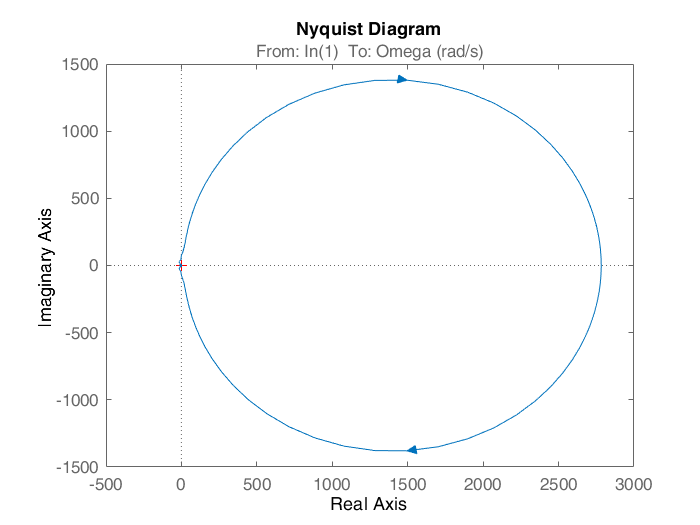

nyqDet=LoopT(1,1)*LoopT(2,2)-LoopT(1,2)*LoopT(2,1);
nyquist(nyqDet)

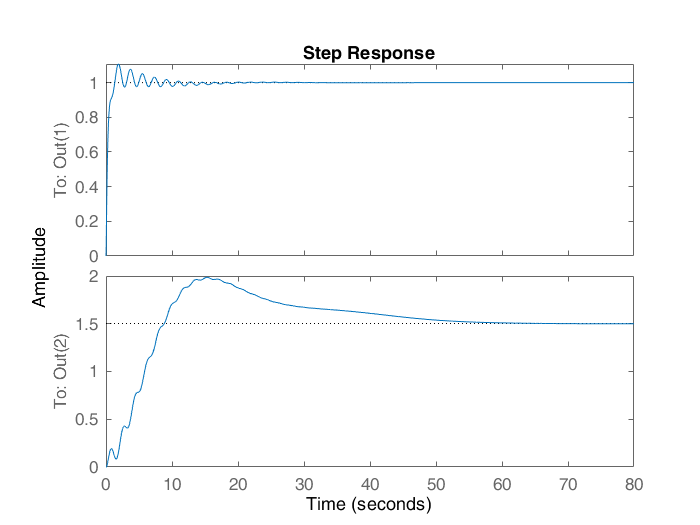

%sysL=feedback(P,K2)
Sens=(1/Wp)*CL2(1:2,1:2);
Compl=eye(2)-Sens;
step(Compl(1:2,1))

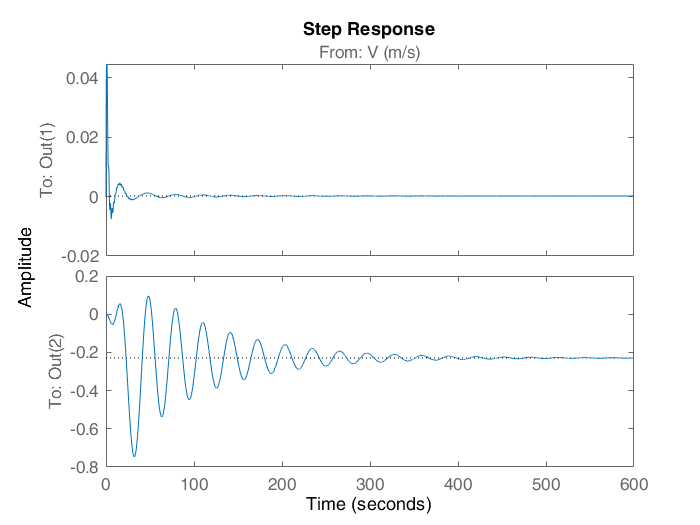


D_rej=Sens*FWT(1:2,3);
step(D_rej)